%This section shows the calibration  of the ocean spectrometer using the
%calibration source. 
Expected1 = [365.015
404.656
407.783
435.833
546.074
576.96
579.066
696.543
706.722
710.748
727.294
738.393
750.387
763.511
772.376
794.818
800.616
811.531
826.452
852.144
866.794
912.297
922.45];

Recorded1 = [367.11
406.46
409.60
438.41
549.29
578.51
580.62
697.97
708.17
716.22
728.82
739.84
751.76
764.92
773.91
796.22
802.32
812.81
827.80
853.51
868.20
913.49
923.72];

%Remember fluctuation of 0.2nm 

Difference1 = Recorded1 - Expected1;
%This equation gives the delta between the expected values and the
%recorded values so that we can calculate the standard deviation.

Average = mean(Difference1)

Average = 1.7920

Standard_derivation = std(Difference1)

Standard_derivation = 0.9246


Standard_error = Standard_derivation/sqrt(length(Difference1))

Standard_error = 0.1928

% This is the associated error on the average

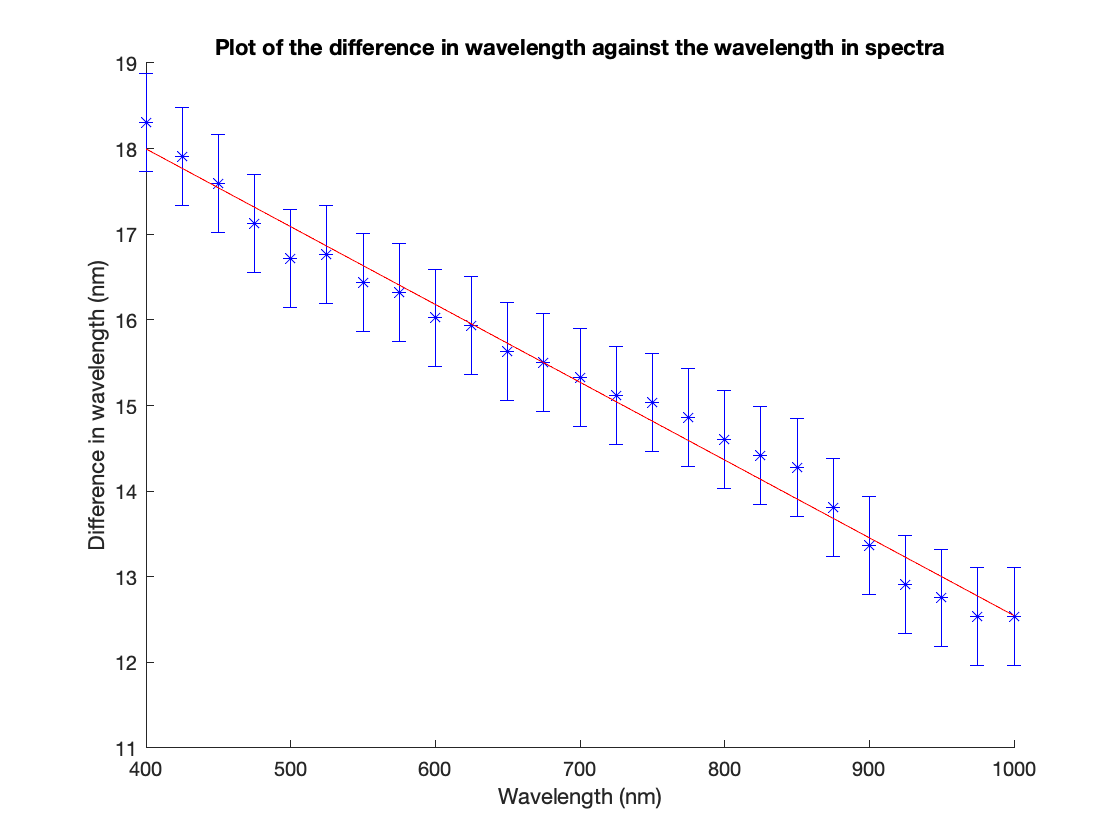

clc

Expected2 = [
400
425
450
475
500
525
550
575
600
625
650
675
700
725
750
775
800
825
850
875
900
925
950
975
1000];

Recorded2 = [416.51
441.12
465.80
490.33
514.93
539.97
564.64
589.53
614.23
639.14
663.84
688.71
713.54
738.33
763.24
788.07
812.81
837.62
862.48
887.02
911.57
936.12
960.96
985.74
1010.74];

Adjusted2 = Recorded2 + Average;

Difference2 = Adjusted2 - Expected2;

standard_deviation2 = std(Difference2);
weights = 1 / standard_deviation2.^2; 
weightsplot = weights*ones(length(Difference2),1);

%Using the standard error approach to combine the standard error on the
%ocean optics offset average and the error of 0.2nm on the read out of the
%wavelengths on the spectrasuite

serror = sqrt(0.2^2 + Standard_error^2 + 0.5^2);
serrorplot = serror * ones(length(Difference2),1);
clf
hold on
errorbar(Expected2,Difference2,serrorplot,'*b')
plot(fittedmodel1)
xlabel('Wavelength (nm)')
ylabel('Difference in wavelength (nm)')
title('Plot of the difference in wavelength against the wavelength in spectra')
legend('off')
hold off